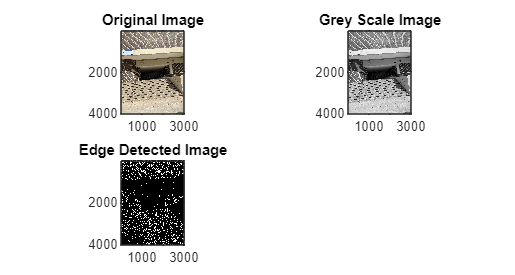

clc;
clear all;
close all;
workspace;  % Make sure the workspace panel is showing.
% Read in original RGB image.
rgbImage  = imread('urbanlife3.jpg');
subplot(2, 2, 1);
imshow(rgbImage)
axis('on', 'image');
title('Original Image')
% Convert to gray scale.
grayImage = rgb2gray(rgbImage);
subplot(2, 2, 2);
imshow(grayImage)
axis('on', 'image');
title('Grey Scale Image')
% Get edges
Canny_img = edge(grayImage, 'Canny');
subplot(2, 2, 3);
imshow(Canny_img, [])
axis('on', 'image');
title('Edge Detected Image')
% Enlarge figure to full screen.
set(gcf, 'Units', 'Normalized', 'Outerposition', [0, 0.05, 1, 0.95]);